**Cystinosis Disease Detector**

Loading the data:

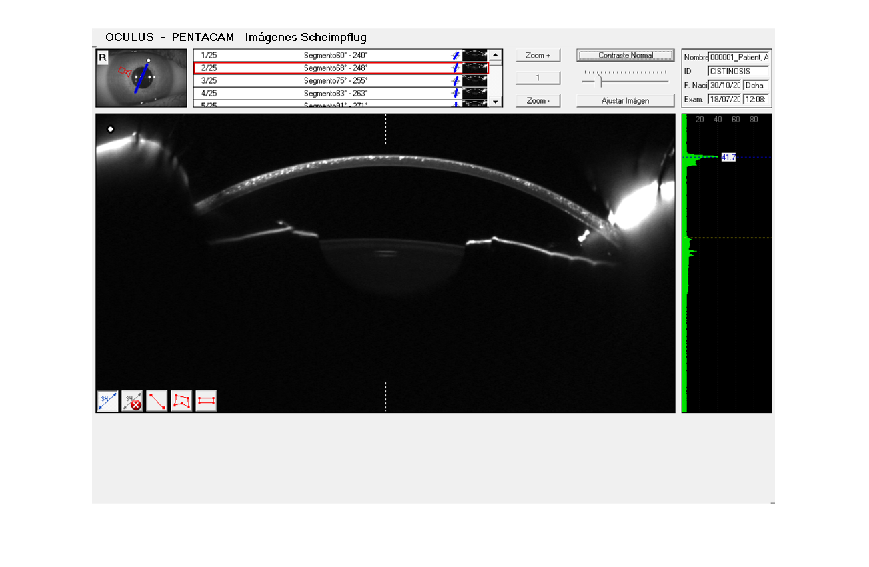

%cd( '../data' )
%patients = dir;
%aux = cell( 1, numel( patients )-2 );
%for i=3:numel( patients)
%    aux{i-2} = patients(i).name;
%end
%patients = aux;

%I = cell( 1, numel( patients ) );
%for i = 1:numel( patients )
%    D = patients{i}; %directory where the files are saved
%    S = dir( fullfile(D,'*.BMP') ); % pattern to match filenames.
%    I{i} = cell( 1, numel(S) );
%    for k = 1:numel(S)
%        F = fullfile( D, S(k).name );
%        I{i}{k} = imread( F );
%        imshow( I{i}{k} );
%    end
%end
I = imread( '../data/OD1con_Cistinosis/CISTINOSIS_20160718_120806_PENTACAM_R_02.BMP' );
figure,
imshow( I );

Pre-processat: per millorar la qualitat de la imatge de manera que és millori el processat posterior (ex: eliminació de soroll, millora contrast, etc).

I = imcrop( I,[0, 130, 870, 410] );
Rmin = 30;
Rmax = 65;

[centersBright, radiiBright] = imfindcircles(I,[Rmin Rmax],'ObjectPolarity','dark');
figure,
viscircles(centersBright, radiiBright,'Color','b')


ans =

     []



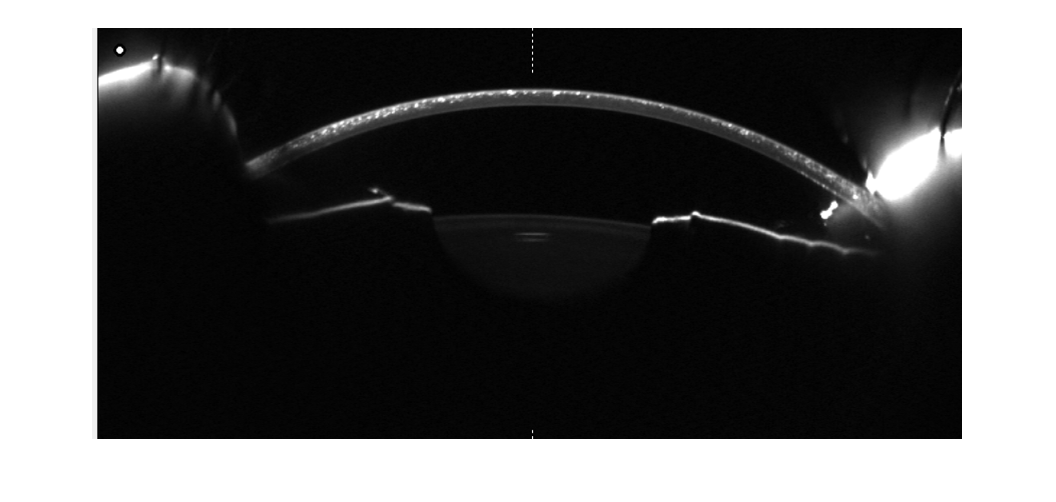

imshow( I );

Obtenció de les característiques necessàries per tal caracteritzar els elements a segmentar.

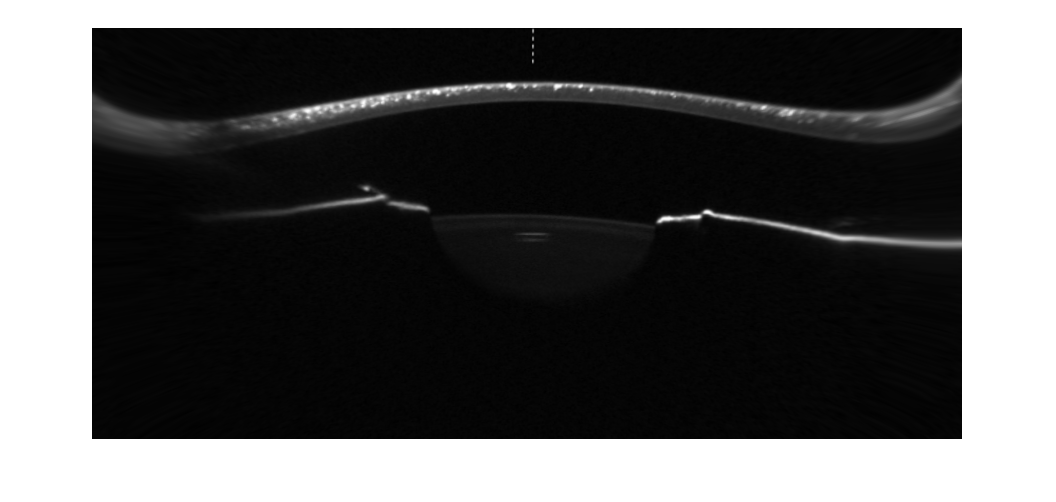

nrows = size(I, 1);
ncols = size(I, 2);
fill = 0.3;
[xi,yi] = meshgrid( 1:ncols, 1:nrows );
xt = xi - ncols/2;
yt = yi - nrows/2;
[theta,r] = cart2pol(xt,yt);

rmax = max( r(:) );

b = 0.456; % Try varying the amplitude of the cubic term.
%b = 0.6;
s = r - r.^3*(b/rmax.^2);

[ut,vt] = pol2cart(theta,s);
ui = ut + ncols/2;
vi = vt + nrows/2;
ifcn = @(c) [ui(:) vi(:)];
tform = geometricTransform2d(ifcn);
I_pin = imwarp(I,tform,'FillValues',fill);
figure,
imshow(I_pin)

Localització dels objectes: segmentar la imatge original per diferenciar els objectes d’interès.

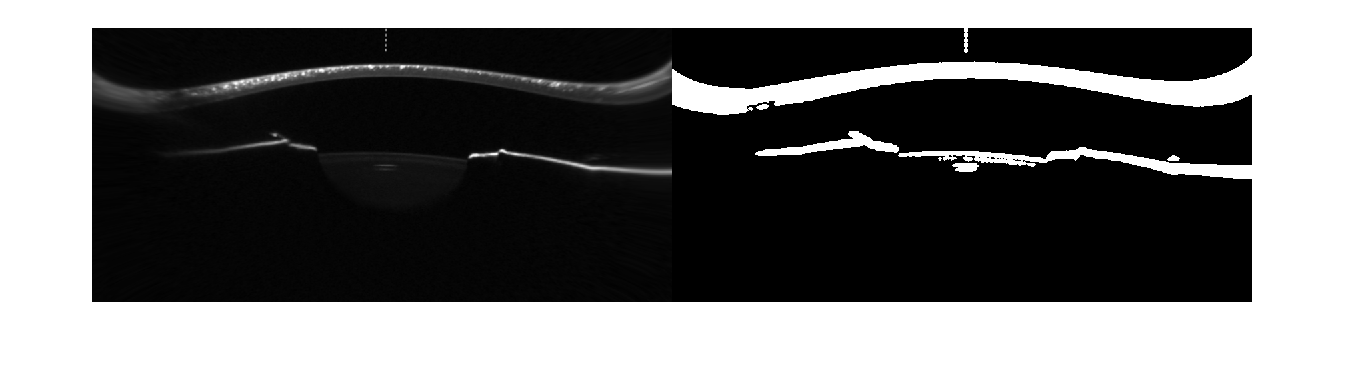

%localitzem la cornia
se = strel( 'disk', 2 );
threshold = 0.1;
thresh = threshold;%graythresh( I_pin ) + threshold
I_pin_b = imbinarize( I_pin, thresh );
%I_pin_b = ~I_pin_b ;
I_pin_b = imdilate( I_pin_b, se);
I_pin_b = imfill( I_pin_b,'holes');
I_pin_b = bwareaopen( I_pin_b,60);
figure,
imshowpair( I_pin, I_pin_b, 'montage' );

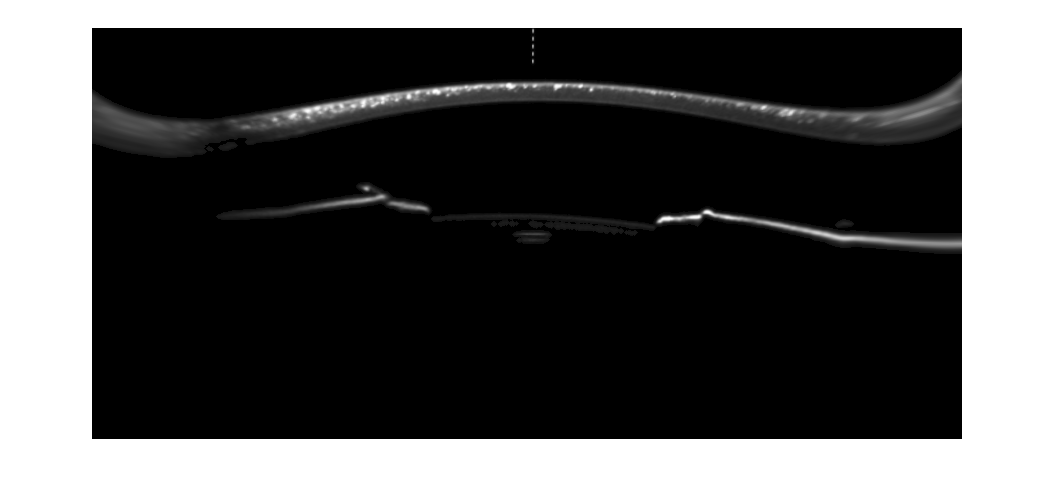


%ens quedem amb la cornia
img = I_pin;
bw = I_pin_b;
Result = bsxfun(@times, img, uint8(bw));
figure,
imshow( Result );    

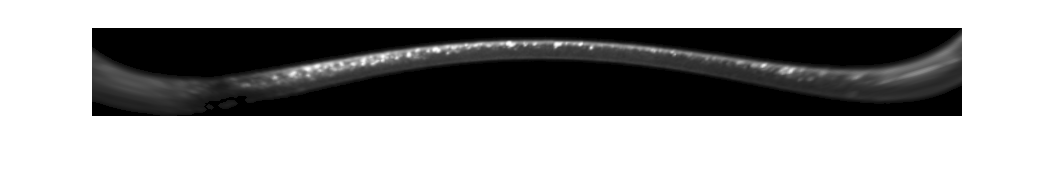



% Apply regionprops to the binary mask
s = regionprops( I_pin_b, 'BoundingBox');
% Create a cell array for the objects
objects = cell(numel(s), 1);
% For each object...
idx = 1;
%// Get the bounding box property
bb = floor( s(idx).BoundingBox );
%// Extract out the object from the segmented image and place in cell array
objects{idx} = Result( bb(2)+1:bb(2)+bb(5), bb(1)+1:bb(1)+bb(4) );
cornea = objects{idx};
figure,
imshow( cornea )

Distingim els cristalls respecte la resta de la imatge mitjaçant una binarització

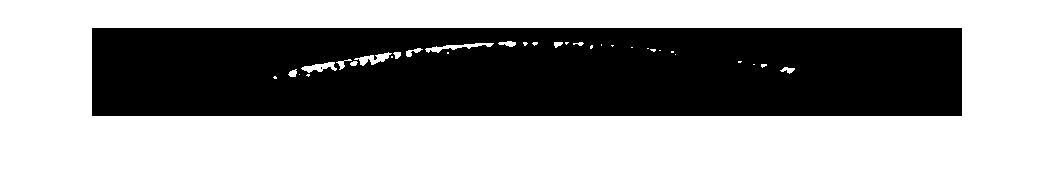

crystals = imbinarize( cornea, 0.625 );
figure,
imshow( crystals);

Amb la informació extreta de la imatge realitzar la tasca demanada.

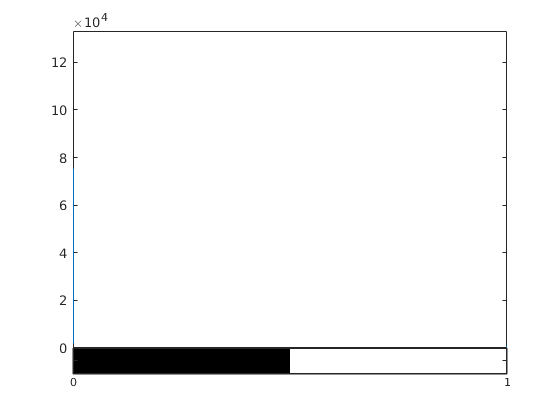

nrows = size(crystals, 1);
ncols = size(crystals, 2);
c_stp = ncols/3;

sec1 = imcrop( crystals, [0, 0, c_stp, nrows]);
sec2 = imcrop( crystals,[c_stp, 0, c_stp, nrows]);
sec3 = imcrop( crystals, [c_stp*2, 0, c_stp, nrows]);

figure,
imhist( crystals )

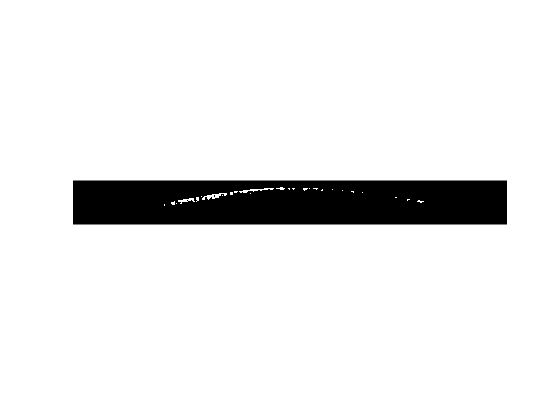

imshow( crystals )

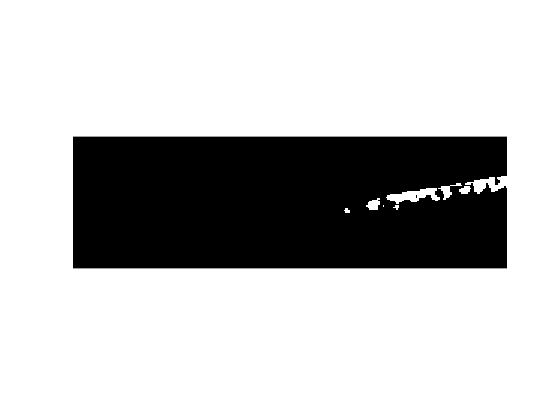

imshow(sec1)

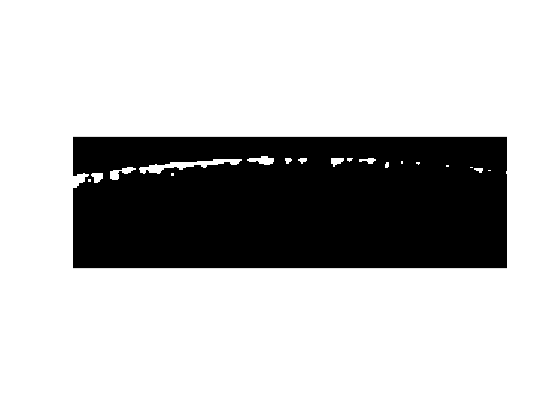

imshow(sec2)

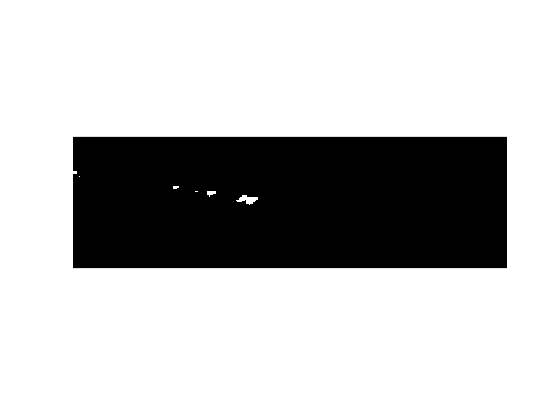

imshow(sec3)


[ counts, binLocations ] = imhist( crystals );
fprintf("The pixel crystals count for this image is: %i", counts(2) )

The pixel crystals count for this image is: 1238